# Heat Diffusion Tutorial

This tutorial will teach you how to set up a steady-state diffusion problem on a membrane using IRACEMA. We will then compare to reference values in the literature.

## Preamble

To make sure everything works fine, we clear the memory and add the IRACEMA scripts to the current path.

clearvars
cd ..
run startup.m
cd UserGuide

## Geometry Definition

The geometry we will be working with is a 0.6m x 1m membrane. We begin creating our model by making two lines, and then creating a ruled surface between these lines.

To keep things clean and easy to access, we will make the first parametric direction be related to the x coordinate and the second parametric direction related to the y coordinate. This is something that can be done in linear cases such as lines and rectangles, but be aware that this won't work in more complex geometries.

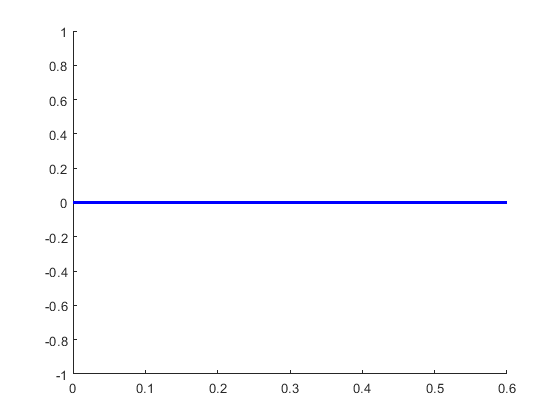

point1 = [0 0 0 1]; % x y z and weight
point2 = [0.6 0 0 1];

Line1 = geo_line(point1, point2);
point3 =
 %Line2 is the same as Line1, but 1m up in y

figure(1)
Line1.plot_geo
hold on

Line2.plot_geo

Array indices must be positive integers or logical values.

Error in CCurvePoint2 (line 8)
    Cw = Cw + N(j+1)*Pw(span-p+j+1);    

Error in PlotRatCurve (line 40)
    	C(i) = CCurvePoint2(n,p,U,Pw,uu(i));

Error in Geometry/plot_geo (line 484)
                PlotRatCurve(obj.nu,obj.pu,obj.U,obj.Pw,Urange,cpoi

With the two lines created, we make a ruled surface between them. We will call this Ruled Surface "Omega", because it will be our function domain.

Omega = geo_ruled(Line1,Line2);
figure(2)
Omega.plot_geo('coarse',1,0)

The plot_geo command has the following syntax:

- render can be 'fine', 'coarse' or 'medium' and relates to the amount of points generated to make the picture.

- ControlPointsBoolean is 1 or 0 and relates to the option of showing or not showing the ControlPoints

- IsolinesBoolean is 1 or 0 and relates to the option of showing or not showing the Isolines (element lines)

### *k*-refinement of the Model

We will make the model have 9-by-15 elements, all of polynomial degree 3, so we need to *k*-refine the model.

Omega.DegreeElevate(2,1); % Elevate u-direction by 2 degrees
Omega.DegreeElevate(2,2); % Elevate v-direction by 2 degrees

uKnots = linspace(0,1,10);
uKnots = setdiff(uKnots, [0 1]); % Making it an open interval

vKnots = linspace(0,1,16);
vKnots = setdiff(vKnots,[0 1]);

Omega.KnotRefine(uKnots,1);
Omega.KnotRefine(vKnots,2);

figure(3)
Omega.plot_geo('coarse',0,1) % Showing Isolines -> Element Separation Lines